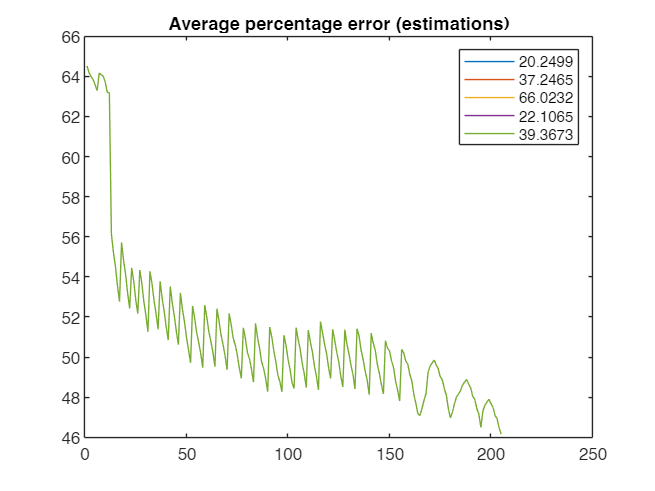

clear;close all;clc;
load('breast08-31-49_patches.mat');
tot_comp=5;

figure;
for j=1:5
    patch = patches.(['val',num2str(j)]);
    a0    = patches.(['a',num2str(j)]);
    ape=zeros(1,size(patch,3));

    for i=1:size(patch,3)
        ape(i)=(est_seabra2008(patch(:,:,i),0,0)-a0)/a0*100;
    end
    plot(ape);hold on;
end
legend(num2str(patches.a1), ...
       num2str(patches.a2), ...
       num2str(patches.a3), ...
       num2str(patches.a4), ...
       num2str(patches.a5) ...
       );
title('Average percentage error (estimations)')

Patch  50
Mean      : 0.002373
Std       : 0.010838
Estimated : 20.2283
Real value: 20.2499
Error     : -0.107%


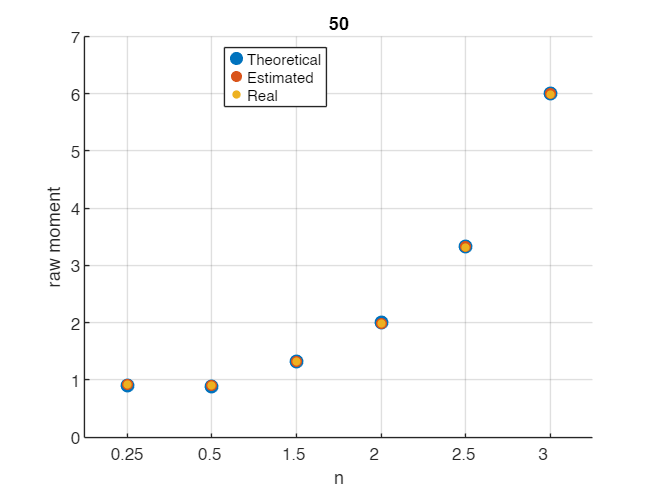


disp('Patch  50');est_prager(patches.val1(:,:, 50),patches.a1,0,true);title( 50);

Patch 100
Mean      : -0.00066351
Std       : 0.018194
Estimated : 20.8994
Real value: 20.2499
Error     : 3.21%


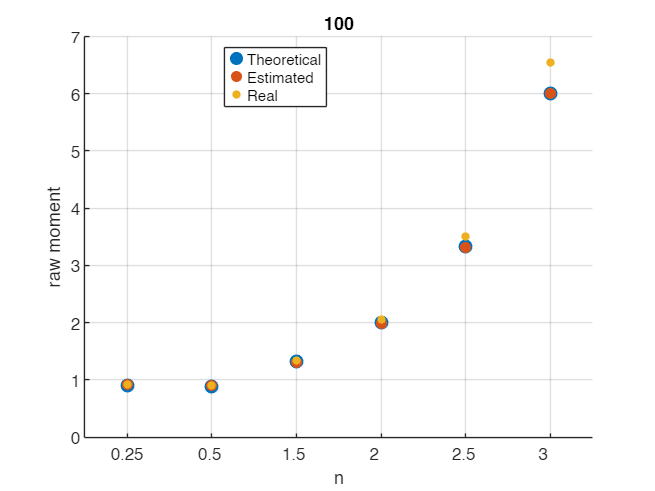

disp('Patch 100');est_prager(patches.val1(:,:,100),patches.a1,0,true);title(100);

Patch 150
Mean      : -0.0038632
Std       : 0.026974
Estimated : 21.8895
Real value: 20.2499
Error     : 8.1%


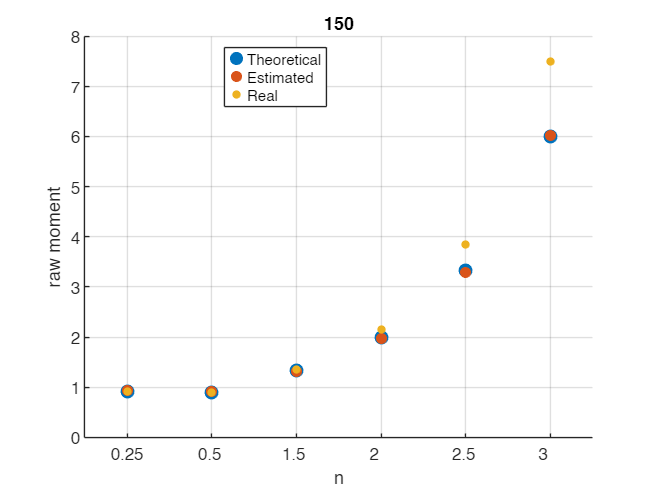

disp('Patch 150');est_prager(patches.val1(:,:,150),patches.a1,0,true);title(150);

Patch 200
Mean      : -0.0091362
Std       : 0.040485
Estimated : 22.5307
Real value: 20.2499
Error     : 11.3%


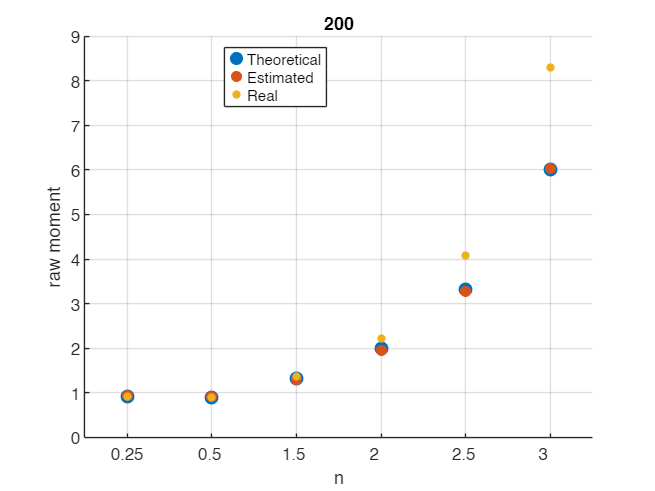

disp('Patch 200');est_prager(patches.val1(:,:,200),patches.a1,0,true);title(200);